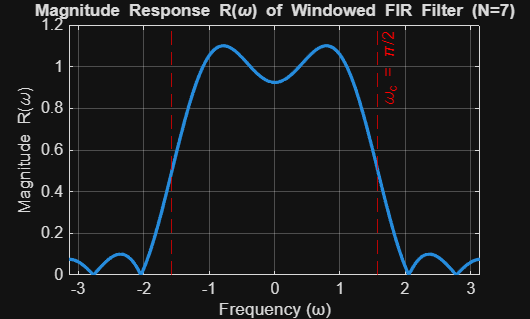

% Question 6.1 b)

% --- Filter Parameters ---
N = 7;             % Length of the rectangular window w[n]
omega_c = 0.5 * pi;% Cutoff frequency of the ideal filter
n_shift = 3;       % Delay to make the filter causal

% --- 1. Define the Time Vector ---
n = 0:N-1;

% --- 2. Create the Ideal Impulse Response (h_id[n-3]) ---
% We use the sinc function form: sin(x)/(pi*x). 
% MATLAB's sinc(x) = sin(pi*x)/(pi*x), so we need to adjust the factor.
% h_id[n-3] = sin(omega_c * (n - n_shift)) / (pi * (n - n_shift))

% To avoid division by zero at n=3, we use an array formula:
h_id = sin(omega_c * (n - n_shift)) ./ (pi * (n - n_shift));

% Correct the value at the center (n=3), where it should be omega_c / pi
h_id(n_shift + 1) = omega_c / pi; 
% h_id(4) = (pi/2) / pi = 0.5

% --- 3. Apply Windowing to get the final impulse response h[n] ---
% The window w[n] is simply 1 over the range n=0 to n=6.
h = h_id; % h is already truncated by the range of n

% --- 4. Compute the Frequency Response R(ω) ---
N_fft = 512;
H_fft = fft(h, N_fft);

% Shift and scale the frequency axis to plot from -pi to pi
R_omega = abs(fftshift(H_fft));
w = linspace(-pi, pi, N_fft);

% --- Plot the Magnitude Response R(ω) ---
figure;
plot(w, R_omega, 'LineWidth', 2);
title('Magnitude Response R(\omega) of Windowed FIR Filter (N=7)');
xlabel('Frequency (ω)');
ylabel('Magnitude R(\omega)');

% Mark the ideal cutoff frequency
xline(omega_c, 'r--', 'Label', '\omega_c = \pi/2');
xline(-omega_c, 'r--');
xlim([-pi pi]);
ylim([0 1.2]); % Ideal passband gain is 1
grid on;

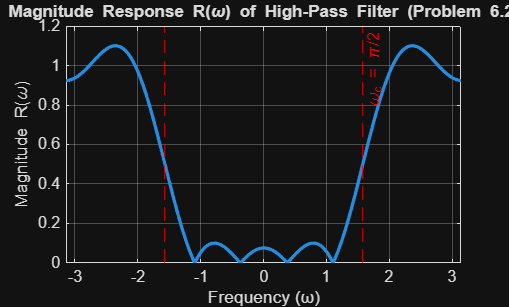

% Question 6.2b)
% --- Filter Parameters ---
N = 7;             % Length of the rectangular window w[n]
omega_c = 0.5 * pi;% Cutoff frequency of the ideal filter
n_shift = 3;       % Delay (N-1)/2 to make the filter causal

% --- 1. Define the Time Vector ---
n = 0:N-1;

% --- 2. Create the Ideal Impulse Response h_id[n-3] ---
% This combines: (sinc function) * ((-1)^n) * (time shift)

% Calculate the base sinc function (h_base[n-3]):
h_base_shifted = sin(omega_c * (n - n_shift)) ./ (pi * (n - n_shift));

% Correct the value at the center (n=3), where the value is omega_c / pi
h_base_shifted(n_shift + 1) = omega_c / pi; 

% Apply the (-1)^n modulation: h_id[n-3] = h_base[n-3] * (-1)^n
% Use (-1).^n to alternate the sign of the base sinc function
h_id = h_base_shifted .* ((-1).^n); 

% --- 3. Apply Windowing (w[n] = 1) to get the final impulse response h[n] ---
h = h_id; % h is already defined and truncated by the range of n

% --- 4. Compute the Frequency Response R(ω) ---
N_fft = 512;
H_fft = fft(h, N_fft);

% Shift and scale the frequency axis to plot from -pi to pi
R_omega = abs(fftshift(H_fft));
w = linspace(-pi, pi, N_fft);

% --- Plot the Magnitude Response R(ω) ---
figure;
plot(w, R_omega, 'LineWidth', 2);
title('Magnitude Response R(\omega) of High-Pass Filter (Problem 6.2)');
xlabel('Frequency (ω)');
ylabel('Magnitude R(\omega)');

% Mark the ideal cutoff frequency
xline(omega_c, 'r--', 'Label', '\omega_c = \pi/2');
xline(-omega_c, 'r--');
xlim([-pi pi]);
ylim([0 1.2]); % Ideal passband gain is 1
grid on;

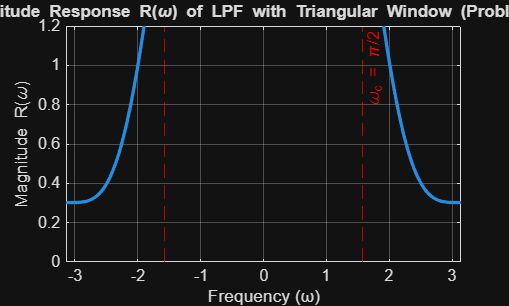

% 6.3b)
% --- Filter Parameters ---
N = 7;             % Length of the filter (Triangular Window)
omega_c = 0.5 * pi;% Cutoff frequency of the ideal filter
n_shift = 3;       % Delay (N-1)/2

% --- 1. Define the Time Vector and Ideal Impulse Response ---
n = 0:N-1;

% Calculate the base sinc function (h_base[n-3]): sin(omega_c * n) / (pi * n)
h_base_shifted = sin(omega_c * (n - n_shift)) ./ (pi * (n - n_shift));

% Correct the value at the center (n=3), where the value is omega_c / pi = 0.5
h_base_shifted(n_shift + 1) = omega_c / pi; 

% --- 2. Create the Triangular Window ---
% The triangular window is a convolution of two rectangular pulses of length L=4.
% It is represented by the formula: 1 - |(n - (N-1)/2) / ((N+1)/2)|, but a simpler
% way is to calculate the convolution of the two shorter rectangular windows.

% Define the two smaller rectangular windows (length L=4)
L_rect = 4;
rect_window = ones(1, L_rect);

% The triangular window w[n] is the convolution of the two rectangular pulses
w_triangular = conv(rect_window, rect_window); 

% We need to center this 7-point result (indices 0 to 6) at the LPF
% h_id is already length 7, so we can use a direct element-wise product.
h_id = h_base_shifted; 

% --- 3. Apply Windowing to get the final impulse response h[n] ---
% Multiply the Ideal LPF (h_id) by the Triangular Window (w_triangular)
h = h_id .* w_triangular; 

% --- 4. Compute the Frequency Response R(ω) ---
N_fft = 512;
H_fft = fft(h, N_fft);

% Shift and scale the frequency axis to plot from -pi to pi
R_omega = abs(fftshift(H_fft));
w = linspace(-pi, pi, N_fft);

% --- Plot the Magnitude Response R(ω) ---
figure;
plot(w, R_omega, 'LineWidth', 2);
title('Magnitude Response R(\omega) of LPF with Triangular Window (Problem 6.3)');
xlabel('Frequency (ω)');
ylabel('Magnitude R(\omega)');

% Mark the ideal cutoff frequency
xline(omega_c, 'r--', 'Label', '\omega_c = \pi/2');
xline(-omega_c, 'r--');
xlim([-pi pi]);
ylim([0 1.2]); 
grid on;